clear;clc;

% load parameters
par_scg = importdata('par_scg_clock.txt');
par_scg = par_scg.data;

par_clock = load('par_clock.csv');
n_clock = 12;

% initial values
y0 = zeros(n_clock+7, 1);
y0(n_clock+1) = 1;
y0(n_clock+4) = 100;

tmax = 1000;
tspan = 0:0.1:tmax;

y = zeros(length(tspan), n_clock+7, 2);
t_V_17 = 523; % from paper CT17 is the acrophase of Bmal1
t_V_6 = 512;

[~, y(:, :, 1)] = ode15s(@ODE_SCG_CLOCK, tspan, y0, [], par_clock, par_scg, t_V_6);
[~, y(:, :, 2)] = ode15s(@ODE_SCG_CLOCK, tspan, y0, [], par_clock, par_scg, t_V_17);
y = real(y);

[~, y_ko] = ode15s(@ODE_SCG_CLOCK_KO, tspan, y0, [], par_clock, par_scg, t_V_17);
y_ko = real(y_ko);

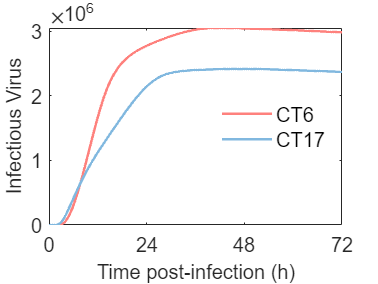

t_V = [t_V_6, t_V_17];
color2 = [254 129 125; 129 184 223] ./ 255;
% Plot virus 
figure; hold on; set(gca,'Fontsize',12, 'FontName', 'Arial'); box on;
for i = 1:2
    plot(tspan - t_V(i), y(:, n_clock+4, i), 'Color', color2(i, :), 'LineWidth', 1.5);
end
% scatter([506+6+48 506+17+48], [4400000 1900000]);
xlim([0 72]);
xticks(0:24:72);
% xticklabels({'0', '24', '48'});
xlabel('Time post-infection (h)','Fontsize',12, 'FontName', 'Arial');
ylabel('Infectious Virus','Fontsize',12, 'FontName', 'Arial');
legend('CT6', 'CT17', 'Box', 'off', 'Location', 'east','Fontsize',12, 'FontName', 'Arial');
set(gcf, 'unit', 'centimeters', 'position', [10 5 8 6]);
hold off;

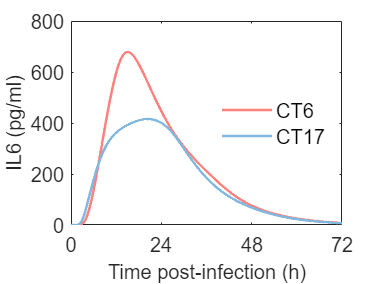

% Plot cytokines IL6
figure; hold on; set(gca,'Fontsize',12, 'FontName', 'Arial'); box on;
for i = 1:2
    plot(tspan - t_V(i), y(:, n_clock+5, i), 'Color', color2(i, :), 'LineWidth', 1.5);
end
xlim([0 72]);
xticks(0:24:72);
xlabel('Time post-infection (h)','Fontsize',12, 'FontName', 'Arial');
ylabel('IL6 (pg/ml)','Fontsize',12, 'FontName', 'Arial');
legend('CT6', 'CT17', 'Box', 'off', 'Location', 'east','Fontsize',12, 'FontName', 'Arial');
set(gcf, 'unit', 'centimeters', 'position', [10 5 8 6]);
hold off;

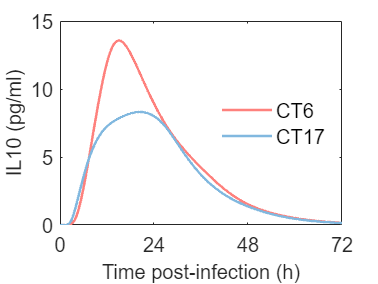

% Plot cytokines IL10
figure; hold on; set(gca,'Fontsize',12, 'FontName', 'Arial'); box on;
for i = 1:2
    plot(tspan - t_V(i), y(:, n_clock+7, i), 'Color', color2(i, :), 'LineWidth', 1.5);
end
xlim([0 72]);
xticks(0:24:72);
xlabel('Time post-infection (h)','Fontsize',12, 'FontName', 'Arial');
ylabel('IL10 (pg/ml)','Fontsize',12, 'FontName', 'Arial');
legend('CT6', 'CT17', 'Box', 'off', 'Location', 'east','Fontsize',12, 'FontName', 'Arial');
set(gcf, 'unit', 'centimeters', 'position', [10 5 8 6]);
hold off;

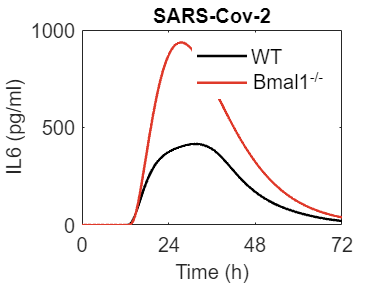


% Plot cytokines of clock KO
figure; hold on; set(gca,'Fontsize',12, 'FontName', 'Arial'); box on;
plot(tspan, y(:, n_clock+5, 2), 'k', 'LineWidth', 1.5);
plot(tspan, y_ko(:, n_clock+5), 'Color', '#DF392A', 'LineWidth', 1.5);
xlim([512 584]);
xticks(512:24:584);
xticklabels({'0', '24', '48', '72'});
xlabel('Time (h)','Fontsize',12, 'FontName', 'Arial');
ylabel('IL6 (pg/ml)','Fontsize',12, 'FontName', 'Arial');
title('SARS-Cov-2','Fontsize',12, 'FontName', 'Arial');
legend('WT', 'Bmal1^{-/-}', 'Box', 'off','Fontsize',12, 'FontName', 'Arial');
set(gcf, 'unit', 'centimeters', 'position', [10 5 8 6]);
hold off;

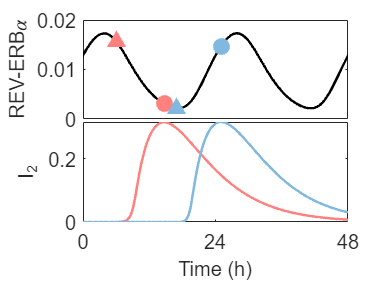

% Plot REV and phases
peak_idx_I2 = zeros(2, 1);    
for i = 1:2
    I2 = y(:, n_clock+3, i);
    [~, peak_idx_I2(i)] = max(I2);
end

figure; hold on; set(gcf, 'unit', 'centimeters', 'position', [10 5 8 6]);
subplot(2, 1, 1); hold on; set(gca,'Fontsize',12, 'FontName', 'Arial'); box on;
set(gca, 'InnerPosition', [0.22 0.58 0.7 0.35]);
plot(tspan, y(:, 8, 1), 'k', 'LineWidth', 1.5);
sz = 100;
% c = [0 0.4470 0.7410; 0.8500 0.3250 0.0980];
scatter((peak_idx_I2-1) ./ 10, y(peak_idx_I2, 8, 1),  sz, color2, 'filled');
scatter([t_V_6, t_V_17], [y(t_V_6 .* 10 + 1, 8, 1), y(t_V_17 .* 10 + 1, 8, 1)], sz, color2, '^', 'filled');
xlim([506 554]);
xticks([]);
ylabel('REV-ERB\alpha','Fontsize',12, 'FontName', 'Arial');
hold off;

subplot(2, 1, 2); hold on; set(gca,'Fontsize',12, 'FontName', 'Arial'); box on;
set(gca, 'InnerPosition', [0.22 0.22 0.7 0.35]);
plot(tspan, y(:, n_clock+3, 1), 'Color', color2(1, :), 'LineWidth', 1.5);
plot(tspan, y(:, n_clock+3, 2), 'Color', color2(2, :), 'LineWidth', 1.5);
xlim([506 554]);
xticks([506 530 554]);
xticklabels({'0', '24', '48'});
xlabel('Time (h)','Fontsize',12, 'FontName', 'Arial');
ylabel('I_2','Fontsize',12, 'FontName', 'Arial');
hold off;

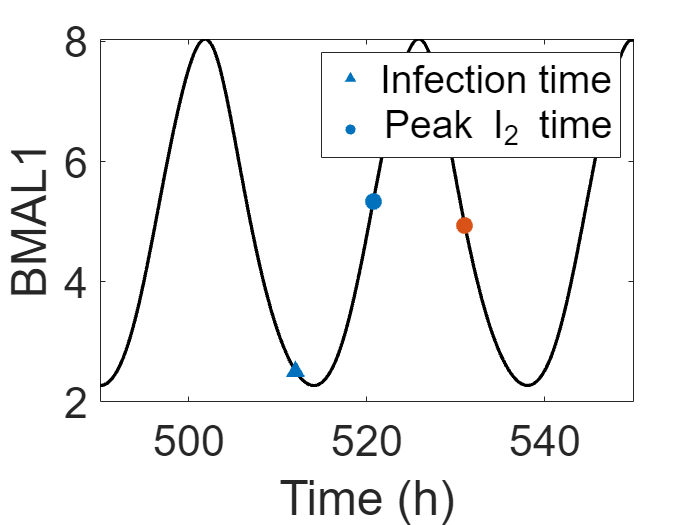


% Plot BMAL1/REV and phases of infection and peak time of I2
peak_idx_I2 = zeros(2, 1);    
for i = 1:2
    I2 = y(:, n_clock+3, i);
    [~, peak_idx_I2(i)] = max(I2);
end
% Plot BMAL1 and phases
figure; hold on; set(gca,'Fontsize',26); box on;
plot(tspan, y(:, 10, 1), 'k', 'LineWidth', 2);
sz = 100;
c = [0 0.4470 0.7410; 0.8500 0.3250 0.0980];
scatter([t_V_6, t_V_17], [y(t_V_6 .* 10 + 1, 10, 1), y(t_V_17 .* 10 + 1, 10, 1)], sz, c, '^', 'filled');
scatter((peak_idx_I2-1) ./ 10, y(peak_idx_I2, 10, 1),  sz, c, 'filled');
xlim([490 550]);
xlabel('Time (h)'); ylabel('BMAL1');
legend('', 'Infection time', 'Peak I_2 time');
hold off;

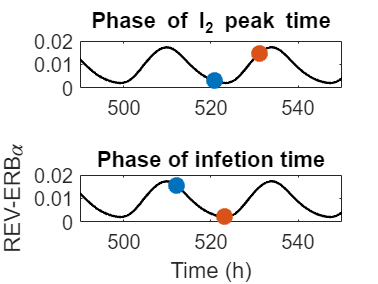

% Plot REV and phases
figure; hold on; set(gcf, 'unit', 'centimeters', 'position', [10 5 8 6]);
subplot(2, 1, 1); hold on; set(gca, 'Fontsize', 12); box on;
plot(tspan, y(:, 8, 1), 'k', 'LineWidth', 1.5);
sz = 100;
c = [0 0.4470 0.7410; 0.8500 0.3250 0.0980];
scatter((peak_idx_I2-1) ./ 10, y(peak_idx_I2, 8, 1),  sz, c, 'filled');
xlim([490 550]);
title('Phase of I_2 peak time');
hold off;

subplot(2, 1, 2); hold on; set(gca, 'Fontsize', 12); box on;
plot(tspan, y(:, 8, 1), 'k', 'LineWidth', 1.5);
sz = 100;
c = [0 0.4470 0.7410; 0.8500 0.3250 0.0980];
scatter([t_V_6, t_V_17], [y(t_V_6 .* 10 + 1, 8, 1), y(t_V_17 .* 10 + 1, 8, 1)], sz, c, 'filled');
xlim([490 550]);
xlabel('Time (h)'); ylabel('REV-ERB\alpha');
title('Phase of infetion time');
hold off;